# Lecture 1: generalized coordinates & kinetic energy

- Find the position vector of point G, $r_G$. 

- Find the velocity vector of point G, $\dot{r_G }$. 

- Find the total kinetic energy of the system $T$. 

Choose the generalized coordinates $q=\left\lbrack \begin{array}{c}
x\\
\theta \;
\end{array}\right\rbrack$.

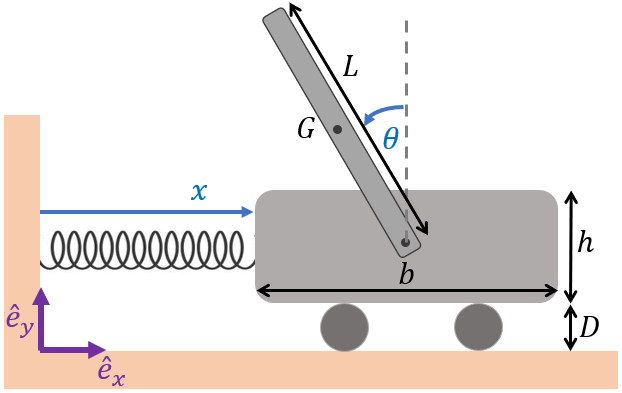

Assume the following properties:

- b = 0.1

- L = 1

- h = 0.4

- D = 0.2

- m_beam = 3

- m_cart = 15

## Position Vector

First calculate the position vector $r_G$. 


$$r_G =\left\lbrack \begin{array}{c}
x+\frac{b}{2}-\frac{L}{2}\sin \left(\theta \;\right)\\
D+\frac{h}{2}+\frac{L}{2}\cos \left(\theta \right)
\end{array}\right\rbrack$$


clc; clear all; close all;

syms x theta x_dot theta_dot

b = 0.1;        % m
L = 1;          % m
h = 0.4;        % m
D = 0.2;        % m
m_beam = 3;     % kg
m_cart = 15;    % kg

% Generalized Coordinates
q = [x;
    theta];
q_dot = [x_dot;
    theta_dot];

% Position Vector
r = [x+b/2-L/2*sin(theta);
    D + h/2 + L/2*cos(theta)]

$$r = \left(\begin{array}{c} x-\frac{\sin\left(\theta \right)}{2}+\frac{1}{20}\\ \frac{\cos\left(\theta \right)}{2}+\frac{2}{5} \end{array}\right)$$

## Velocity Vector

In general $r_G =r_G \left(q,t\right)$. Differentiating with respect to time yields the velocity vector.


$$\dot{r_G } ={r_G }_{,q} \dot{q} +{r_G }_{,t}$$


Since there are no prescribed displacements ($s=0$)


$$\dot{r_G } =r_{,q} \dot{q}$$


% Velocity Vector
drdq = jacobian(r,q);
r_dot = drdq*q_dot

$$r\_dot = \left(\begin{array}{c} \dot{x}-\frac{\dot{\theta }\,\cos\left(\theta \right)}{2}\\ -\frac{\dot{\theta }\,\sin\left(\theta \right)}{2} \end{array}\right)$$

## Kinetic Energy

The kinetic energy of a single rigid body is


$$T=\frac{1}{2}m{\dot{r_G } }^{T\;} \dot{r_G } +\frac{1}{2}J_G \omega {\;}^2$$


In this case, there are two rigid bodies (the beam and the cart) so the total kinetic energy is $T=T_{\textrm{beam}} +T_{\textrm{cart}}$ 

%% Beam
% kinetic energy beam
T_beam_trans = 0.5*m_beam*transpose(r_dot)*r_dot;
T_beam_rot = 0.5*(1/12*m_beam*L^2)*theta_dot^2;
T_beam = T_beam_trans + T_beam_rot;

%% Cart
% position vector to CoM of cart
r = [x+b/2;
    D+h/2];

% velocity vector
drdq = jacobian(r,q);
r_dot = drdq*q_dot;

% kinetic energy cart
T_cart_trans = 0.5*m_cart*transpose(r_dot)*r_dot;
T_cart_rot = 0;
T_cart = T_cart_trans + T_cart_rot;

%% Kinetic Energy System
T = T_beam + T_cart;
T = simplify(T)

$$T = \frac{{\dot{\theta }}^{2}}{2}-\frac{3\,\cos\left(\theta \right)\,\dot{\theta }\,\dot{x}}{2}+9\,{\dot{x}}^{2}$$